# Chap 4 - Retrieval Augmented Generation

### Traditional Search

DuckDuckGo can be used as a free search engine, as it provides an API that enables to parse the search results as JSON without API key (alternative exists based on Google and other search engines).

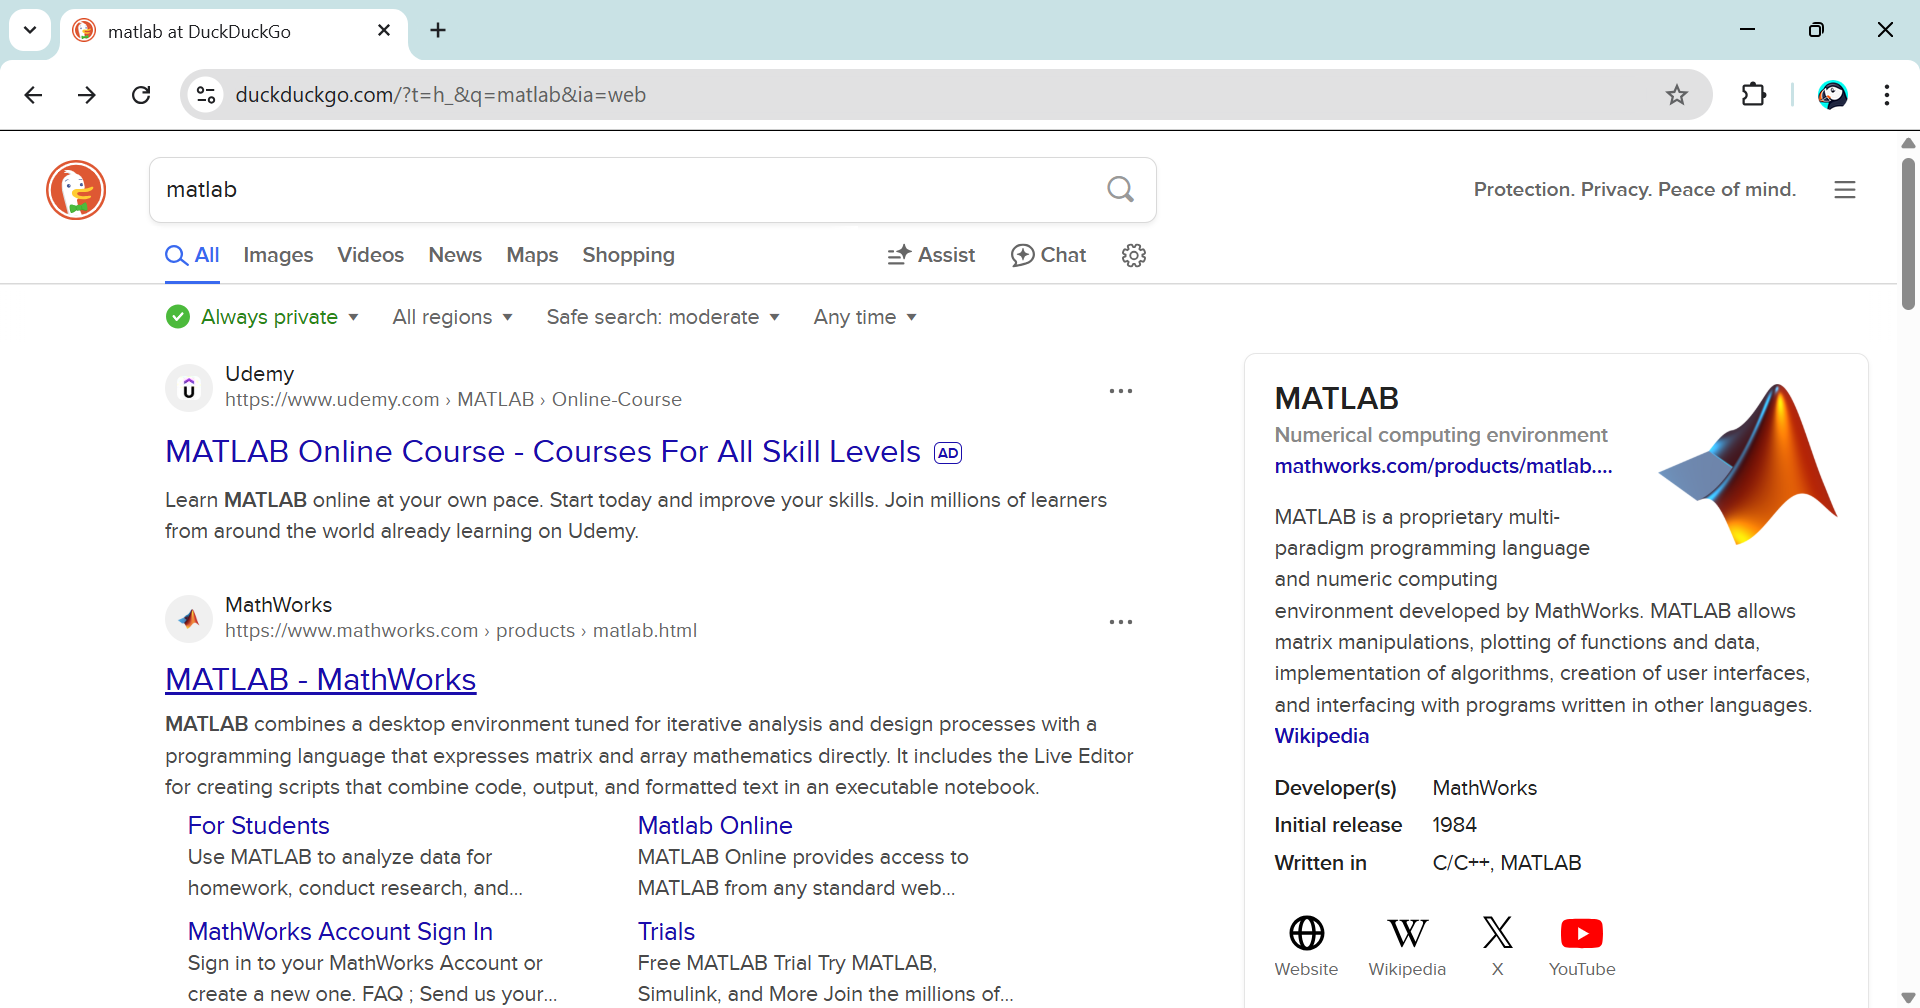

[https://duckduckgo.com/?q=matlab&ia=web](https://duckduckgo.com/?q=matlab&ia=web)

Here is an example of a similar query, but made this time to the DuckDuckGo API programmatically.

% Set up the query
query = "what is MATLAB?";
% URL encode the query string to handle special characters and spaces
query = urlencode(query)

query = 'what+is+MATLAB%3F'

% Construct the base URL for the DuckDuckGo API
url = "https://api.duckduckgo.com/?format=json&q="+query;
% Make the API request
options = weboptions('ContentType', 'json');
res = webread(url, options);

% Display the response title and abstract
disp("Heading: " + res.Heading)

Heading: MATLAB


disp("Abstract: " + res.Abstract)

Abstract: MATLAB is a proprietary multi-paradigm programming language and numeric computing environment developed by MathWorks. MATLAB allows matrix manipulations, plotting of functions and data, implementation of algorithms, creation of user interfaces, and interfacing with programs written in other languages. Although MATLAB is intended primarily for numeric computing, an optional toolbox uses the MuPAD symbolic engine allowing access to symbolic computing abilities. An additional package, Simulink, adds graphical multi-domain simulation and model-based design for dynamic and embedded systems. As of 2020, MATLAB has more than four million users worldwide. They come from various backgrounds of engineering, science, and economics. As of 2017, more than 5000 global colleges and universities use MATLAB to support instruction and research.


Parse the first result.

wiki = webread(res.AbstractURL);
context = extractHTMLText(wiki);

Use the context of the search result to provide a response.

prompt = ["Based on the following context, answer the query:";
          "-------";
          "Context:";
           context;
          "-------";
          "Query:";
           query];
prompt = strjoin(prompt,newline);
model = openAIChat();
response = generate(model,prompt)

response = "MATLAB is a proprietary multi-paradigm programming language and numerical computing environment developed by MathWorks. The name "MATLAB" stands for "MATrix LABoratory," and it is designed primarily for numeric computation but can also facilitate matrix manipulations, plotting of functions and data, implementation of algorithms, and creating user interfaces. MATLAB supports various functionalities, including interfacing with programs written in other languages, and has optional toolboxes for symbolic computing and graphical multi-domain simulation through Simulink. It can run on multiple operating systems such as Windows, macOS, and Linux. MATLAB is widely used across various fields, including engineering, science, and economics."

This API only provides instant results, not full search.

For this, let's use the Python package `duckduckgo-search`

query = "Who's the last CEO of twitter?";
T = search(query)

T = 10×3 table
                                      title                                                                                        href                                                                                                                                                                                                                                                            body                                                                                                                                                                                                      
    __________________________________________________________________________    _______________________________________________________________________________________________________    _________________________________________________________________________________________________________________

for i = 1:3 %height(T)
    c = extractHTMLText(webread(T.href(i)));
    T.tokens(i) = tokenizedDocument(c);
end

embQuery = bm25Similarity(T.tokens, tokenizedDocument(query));
[embQuery, idx] = sort(embQuery, "descend");
T.title(idx(1))

ans = "Elon Musk confirms Twitter's new CEO is ad guru Linda Yaccarino from ..."

### Utils

Search based on DuckDuckGo

function T = search(query)
    ddgs = py.duckduckgo_search.DDGS();
    res = ddgs.text(query);
    df = py.pandas.DataFrame(res);
    T = table(df);
end

Retrieval Augmented Generation based on keyword search:

[https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/examples/RetrievalAugmentedGenerationUsingChatGPTandMATLAB.md](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/examples/RetrievalAugmentedGenerationUsingChatGPTandMATLAB.md)